global K q Vg n Voc Isc1 T1 Ko S1;
K = 1.381e-23;                      % Boltzmann Constant
q = 1.6e-19;                        % Charge
Vg = 1.12;                          % Band Gap
n = 72;                             % Number of cells
Voc = 44.8;                         % V open circuit
Isc1 = 5.5;                         % Short circuit current STC
T1 = 298;                           % STC tempreature
Ko = 0.00065;                       % Temperature Coefficient
S1 = 1000;                          % Light intensity
VMPP = 36.5;                        % Voltage of max power
IMPP = 5.1;                         % Current at max power
T = 300;                             % temp in kelvin
irrad = 1000 ;                       %irradiance in watt/m2



% Defining the variables for model creation
IL1 = IrradianceCurrent(T1,S1);     % Photonic current in STC

[finaly,finalRs,finalRsh] = modelDesigner(IL1,Voc,VMPP,IMPP) % find the appropriate model

     0



finaly = 1.0200

finalRs = 0.0090

finalRsh = 50

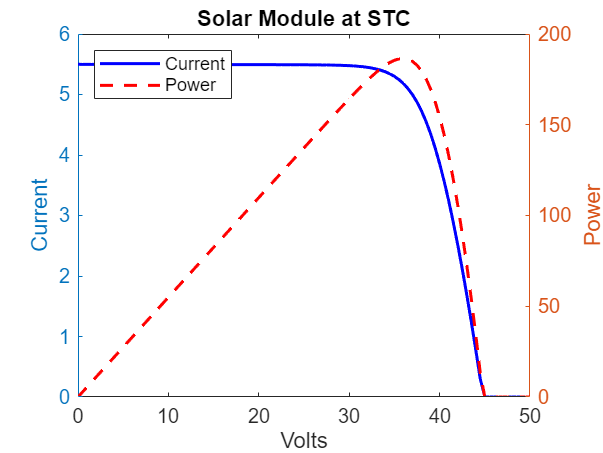


Is1 = ReverseCurrentSTC(finaly);    % Reverse saturation current in STC

%Initializing voltage, current and power values for plotting
V = 0:0.5:50;
outputCurrents = zeros(size(V));
power = zeros(size(V));
% using model parameters for plotting
for i = 1:length(V)
    outputCurrents(i) = currentNewton(IL1,0,Is1,V(i),finalRs,finaly,298,finalRsh);
    power(i) = outputCurrents(i)*(V(i));
end

% Create the plot at STC
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module at STC');
legend('Current', 'Power', 'Location', 'northwest');

% PVmod function call
voltinp = 0:1:40;
irradinp = 1000;
tempinp = 298;
Curr = PVmod(voltinp,irradinp,tempinp,finaly,finalRs,finalRsh)

Curr =     5.4990    5.4987    5.4985    5.4982    5.4979    5.4976    5.4973    5.4971    5.4968    5.4965    5.4962    5.4960    5.4957    5.4954    5.4951    5.4948    5.4946    5.4943    5.4940    5.4937    5.4934    5.4931    5.4927    5.4923    5.4917    5.4911    5.4901    5.4886    5.4863    5.4826    5.4764    5.4663    5.4495    5.4214    5.3753    5.3002    5.1808    4.9973    4.7277    4.3525    3.8596


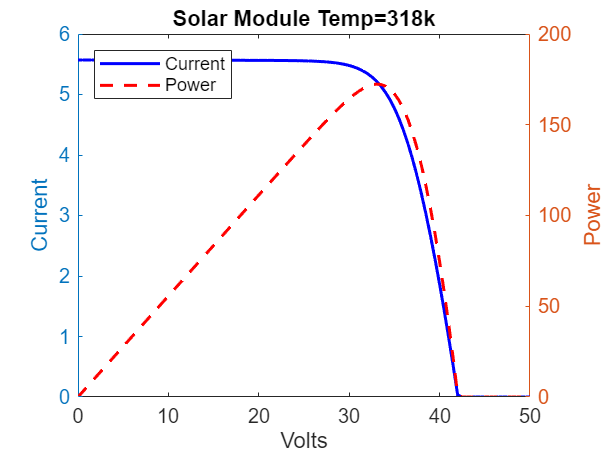

% For different Tempreatures
% IL25 = IrradianceCurrent(298,1000);
IL45 = IrradianceCurrent(318,1000);
IL70 = IrradianceCurrent(343,1000);
IS45 = ReverseCurrent(Is1,318,finaly);
IS70 = ReverseCurrent(Is1,343,finaly);
outputCurrents45 = zeros(size(V));
power45 = zeros(size(V));
outputCurrents70 = zeros(size(V));
power70 = zeros(size(V));
for i = 1:length(V)
    outputCurrents45(i) = currentNewton(IL45,0,IS45,V(i),finalRs,finaly,318,finalRsh);
    outputCurrents70(i) = currentNewton(IL70,0,IS70,V(i),finalRs,finaly,343,finalRsh);
    power45(i) = outputCurrents45(i)*(V(i));
    power70(i) = outputCurrents70(i)*(V(i));;
end
% Create the plot for Temperature of 45 degrees celsius
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents45, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power45, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Temp=318k');
legend('Current', 'Power', 'Location', 'northwest');

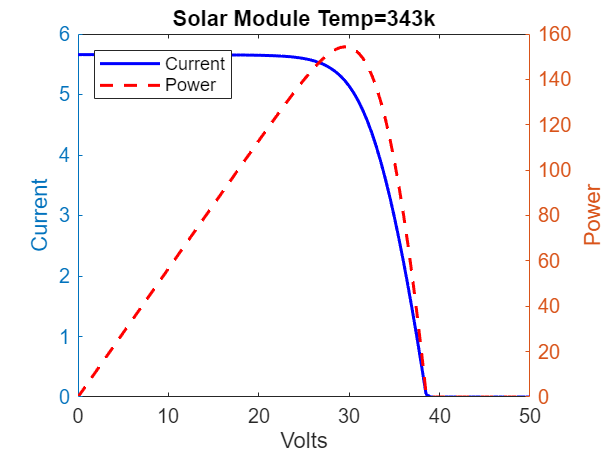



% Create the plot for Temperature of 70 degrees celsius
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents70, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power70, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Temp=343k');
legend('Current', 'Power', 'Location', 'northwest');

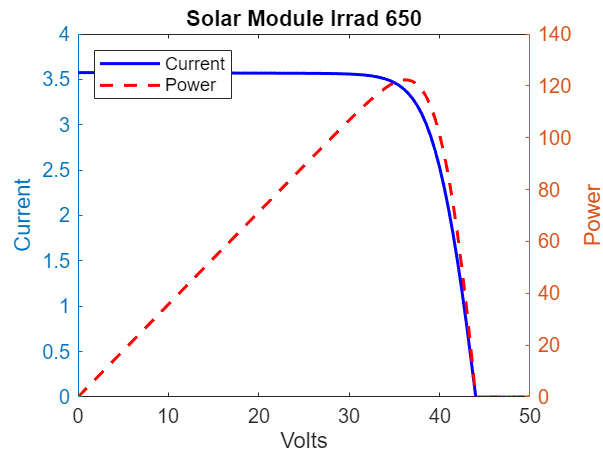

% For different Irradiances
IL650 = IrradianceCurrent(T1,650);
IL300 = IrradianceCurrent(T1,300);
IS650 = ReverseCurrent(Is1,T1,finaly);
IS300 = ReverseCurrent(Is1,T1,finaly);
outputCurrents650 = zeros(size(V));
power650 = zeros(size(V));
outputCurrents300 = zeros(size(V));
power300 = zeros(size(V));
for i = 1:length(V)
    outputCurrents650(i) = currentNewton(IL650,0,IS650,V(i),finalRs,finaly,T1,finalRsh);
    outputCurrents300(i) = currentNewton(IL300,0,IS300,V(i),finalRs,finaly,T1,finalRsh);
    power650(i) = outputCurrents650(i)*(V(i));
    power300(i) = outputCurrents300(i)*(V(i));
end

% Create the plot for Irrad 650
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents650, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label
    
% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power650, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Irrad 650');
legend('Current', 'Power', 'Location', 'northwest');

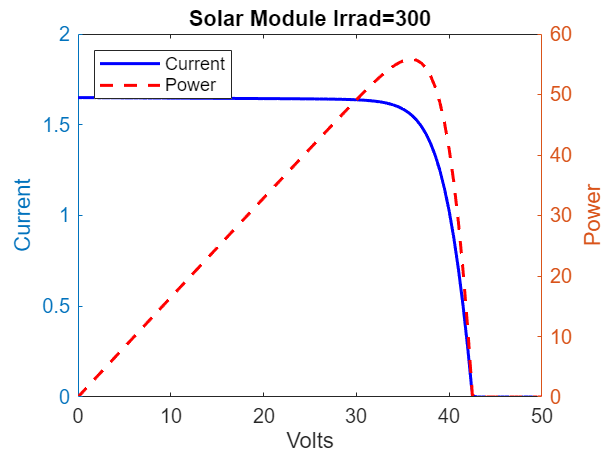



% Create the plot for Irrad 300
figure;

% Plot data for the Current
yyaxis left;           % Activate the left Y-axis
plot(V, outputCurrents300, 'b-', 'LineWidth', 1.5);  % Plot y1 with a blue solid line
ylabel('Current');      % Label for the left Y-axis
xlabel('Volts');      % X-axis label

% Plot data for the Power
yyaxis right;          % Activate the right Y-axis
plot(V, power300, 'r--', 'LineWidth', 1.5); % Plot y2 with a red dashed line
ylabel('Power');   % Label for the right Y-axis

% Title
title('Solar Module Irrad=300');
legend('Current', 'Power', 'Location', 'northwest');

% Efficiency
A = 2;       %Area
S = 1000;    %Irradiance

moduleEfficiency = (VMPP*IMPP)/(A*S)

moduleEfficiency = 0.0931

% Fill Factor
FF = (VMPP*IMPP)/(Voc*Isc1)

FF = 0.7555